close all; clear;

rootdir = 'C:\Users\matth\Documents\MPhil\Data';
cd (rootdir)

addpath(genpath('tapas\tapas-master\HGF'));

file_location = [rootdir, '\MatSep\Rodent_Data_PreAdultStress.csv']

file_location = 'C:\Users\matth\Documents\MPhil\Data\MatSep\Rodent_Data_PreAdultStress.csv'

opts = detectImportOptions(file_location);
opts = setvartype(opts, opts.VariableNames{1}, 'string'); % Set the first column to type 'string'
data = readtable(file_location, opts); % Change input file

### Data Wrangling

data.log_Response_Latency = log(data.Response_Latency) ;

data.Task_Type = zeros(size(data,1), 1);
data.Task_Type(ismember(data.Session, [4 5 6])) = 1;
data1 = data(data.Task_Type == 0, :);
data2 = data(data.Task_Type == 1, :);

group_counts1 = groupsummary(data1, 'Index');
valid_indices1 = group_counts1.Index(group_counts1.GroupCount == 160);
finaldata1 = data1(ismember(data1.Index, valid_indices1), :);

[~, ~, newIndex] = unique(finaldata1.Index, 'stable');
finaldata1.NewRunIndex = newIndex;

group_counts2 = groupsummary(data2, 'Index');
valid_indices2 = group_counts2.Index(group_counts1.GroupCount == 180);
finaldata2 = data2(ismember(data2.Index, valid_indices2), :);

[~, ~, newIndex] = unique(finaldata1.Index, 'stable');
finaldata1.NewRunIndex = newIndex;

%save("modelling_task1.mat")

### Configuring Model

three_level_model_config = tapas_ehgf_binary_config(); % perceptual model
ar1_model_config = tapas_ehgf_ar1_binary_config();
two_level_model_config = tapas_ehgf_binary_config();
sutton_model_config = tapas_sutton_k1_binary_config();
rw_model_config = tapas_rw_binary_config();
softmax_model_config = tapas_softmax_binary_config();%tapas_logrt_linear_binary_config(); % response model
unitsq_model_config = tapas_unitsq_sgm_config();
unitsq_mu3_config = tapas_unitsq_sgm_mu3_config();
comb_model_config = m1_comb_obs_config();
optim_config     = tapas_quasinewton_optim_config(); % optimisation algorithm

optim_config.nRandInit = 10;

## Obtaining Priors

### Plotting True Behavioural Data

trials = 1:160;
plottingdata = finaldata1;
plottingdata.Choice(plottingdata.Choice == 1) = 0.9;
plottingdata.Choice(plottingdata.Choice == 0) = 0.1;

for i = 1:plottingdata.NewRunIndex(end)
    sessiondata = plottingdata(plottingdata.NewRunIndex == i, :);
    figHandle = figure; 
    fig = plot(trials, sessiondata.Choice, 'or', trials, sessiondata.Correct_Side, 'og');
    set(fig(1), 'MarkerFaceColor', 'r');
    set(fig(2), 'MarkerFaceColor', 'g');
    exportgraphics(figHandle, 'Choices_Figures.pdf', 'Append', true);
    close(figHandle);
end

### Bayes Optimal Prior Means

percNames = {"rw", "hgf2l", "hgf3l", "hgfar1", "sutton"};
percArgs = {rw_model_config, two_level_model_config, three_level_model_config, ar1_model_config, sutton_model_config};

for i = 1:numel(percNames)
    for j = 1:(finaldata1.NewRunIndex(end))
        sessiondata = finaldata1(finaldata1.NewRunIndex == j, :);
        bopars = tapas_fitModel([], ...
            sessiondata.Correct_Side, ...
            percArgs{i}, ...
            'tapas_bayes_optimal_binary_config', ...
            'tapas_quasinewton_optim_config'); 
        priors.(percNames{i})(j, :) = bopars.p_prc.p;
    end
    percArgs{i}.priorsmus = mean(priors.(percNames{i}));
end

two_level_model_config.omsa = [NaN, 4, 0];
two_level_model_config.logkamu = [log(1), -Inf];
two_level_model_config = tapas_align_priors(two_level_model_config);

save("bopriors_task1.mat")

### Reduced Standard Deviation for Priors

% SDs have been halved for all observational priors


### Sampling from Bayes Optimal Priors

%load("bopriors_task1.mat")
obsNames = {"softmax", "unitsq", "unitsq_mu3"};
obsArgs = {softmax_model_config, unitsq_model_config, unitsq_mu3_config};
sessiondata = finaldata1(finaldata1.NewRunIndex == 1, :);

for i = 1:numel(obsNames)
    for j = 1:numel(percNames)
        for h = 1:100
        if obsNames{i} == "unitsq_mu3" && (percNames{j} == "rw" || percnames{j} == "sutton")
        continue
        end
        
        samples4.(obsNames{i}).(percNames{j})(h) = tapas_sampleModel(sessiondata.Correct_Side, percArgs{j}, obsArgs{i});
        
        if j == 1
            tapas_rw_binary_plotTraj(samples3.(obsNames{i}).(percNames{j})(h));
        elseif j == 5
            tapas_sutton_k1_binary_plotTraj(samples3.(obsNames{i}).(percNames{j})(h));
        else
            tapas_ehgf_binary_plotTraj(samples3.(obsNames{i}).(percNames{j})(h));
        end
        
        fig = gcf;
        filename = "Sample4_" + percNames{j} + obsNames{i} + ".pdf";
        exportgraphics(fig, filename, 'Append', true);

        end
    end
end

Ignored trials: none


Ignored trials: none


Ignored trials: none


Ignored trials: none


Ignored trials: none


Ignored trials: none


Ignored trials: none


Ignored trials: none


Ignored trials: none


Ignored trials: none


Ignored trials: none


Ignored trials: none


Unable to resolve the name 'samples.softmax.rw'.

### Changing Priors

The rodent behaviour is more stochastic than that generated by sampling from the bayes optimal priors.

softmax_model_config.logbemu = log(24);
unitsq_model_config.logzemu = log(24);

## Fitting

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parame

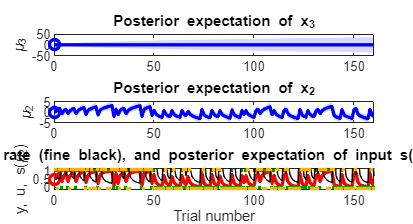

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -8.3999 2]

 
Parameter estimates for the observation model:
    ze: 2.4719

Model quality:
    LME (more is better): -

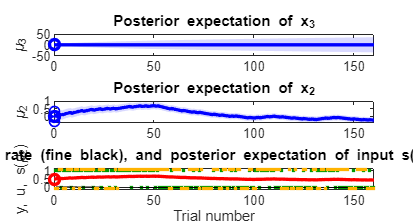

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -0.0374 2]

 
Parameter estimates for the observation model:
    ze: 1.3023

Model quality:
    LME (more is better): -

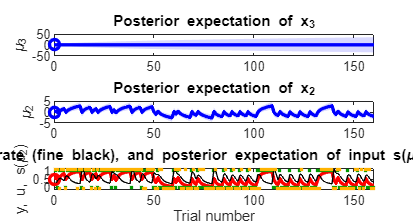

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -4.0139 2]

 
Parameter estimates for the observation model:
    ze: 1.5024

Model quality:
    LME (more is better): -

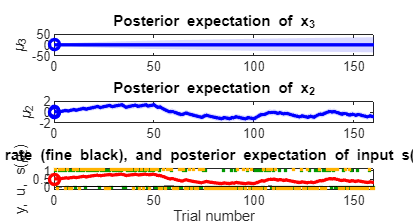

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -0.2220 2]

 
Parameter estimates for the observation model:
    ze: 0.8183

Model quality:
    LME (more is better): -

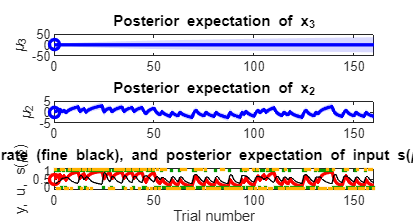

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -5.1622 2]

 
Parameter estimates 

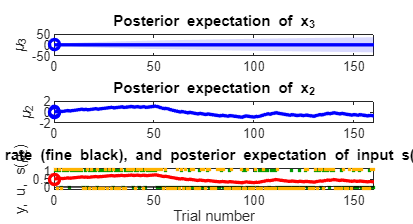

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN 0.0501 2]

 
Parameter estimates for the observation model:
    ze: 1.6365

Model quality:
    LME (more is better): -7

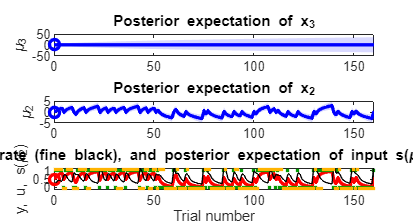

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -0.0148 2]

 
Parameter estimates for the observation model:
    ze: 1.1868

Model quality:
    LME (more is better): -

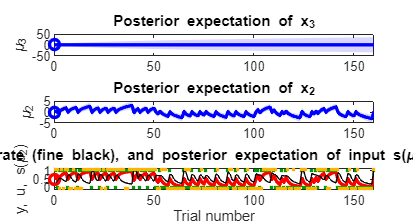

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN 0.2363 2]

 
Parameter estimates f

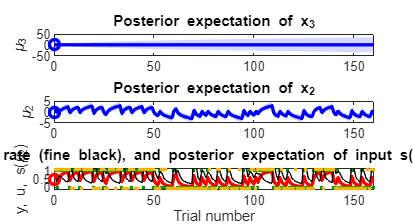

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN 0.1859 2]

 
Parameter estimates for the observation model:
    ze: 1.5459

Model quality:
    LME (more is better): -7

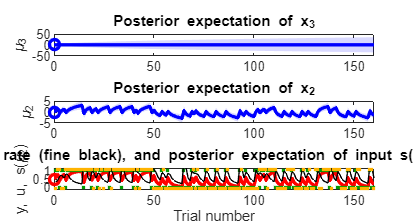

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -0.6448 2]

 
Parameter estimates for the observation model:
    ze: 0.9599

Model quality:
    LME (more is better): -

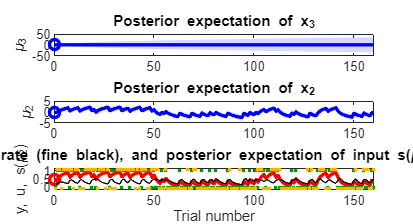

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -0.6460 2]

 
Parameter estimates 

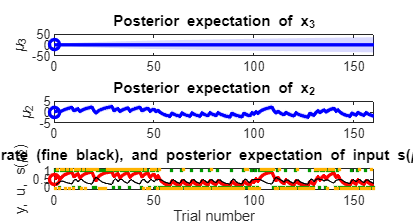

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -0.0251 2]

 
Parameter estimates for the observation model:
    ze: 1.3219

Model quality:
    LME (more is better): -

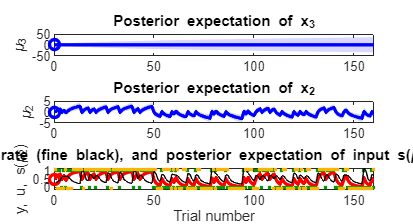

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -0.4508 2]

 
Parameter estimates for the observation model:
    ze: 1.1829

Model quality:
    LME (more is better): -

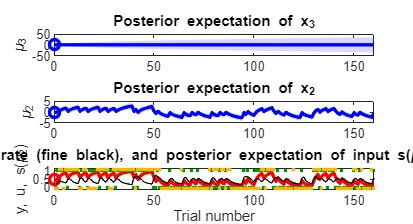

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -1.3655 2]

 
Parameter estimates 

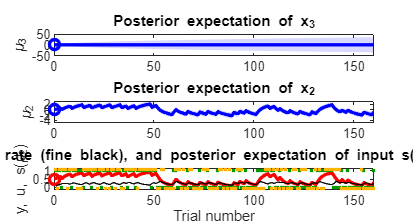

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN 0.4773 2]

 
Parameter estimates for the observation model:
    ze: 0.5991

Model quality:
    LME (more is better): -1

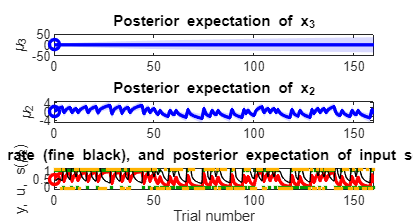

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]


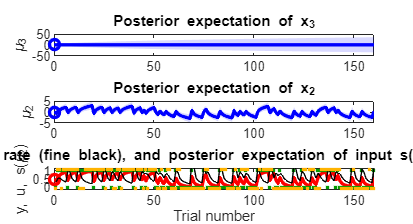

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -3.6561 2]

 
Parameter estimates for the observation model:
    ze: 1.4442

Model quality:
    LME (more is better): -

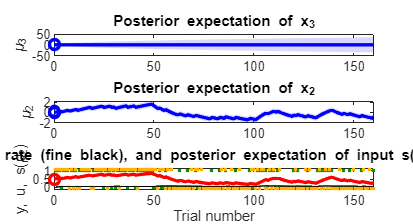

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -5.0692 2]

 
Parameter estimates 

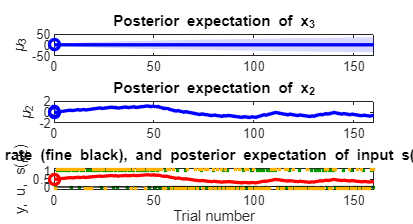

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -0.5254 2]

 
Parameter estimates for the observation model:
    ze: 0.7419

Model quality:
    LME (more is better): -

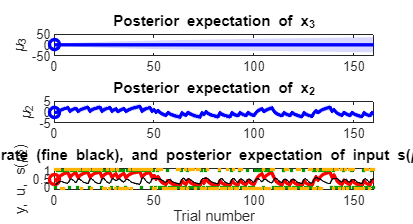

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN 0.1210 2]

 
Parameter estimates f

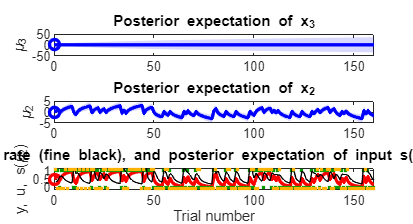

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -0.6882 2]

 
Parameter estimates 

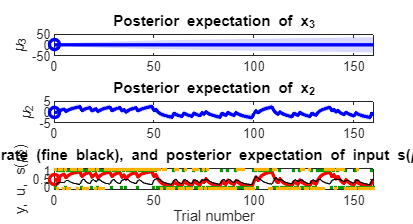

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parame

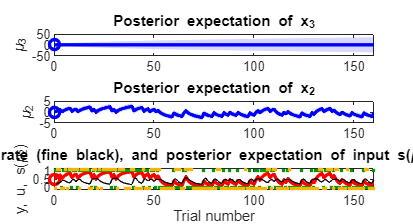

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]


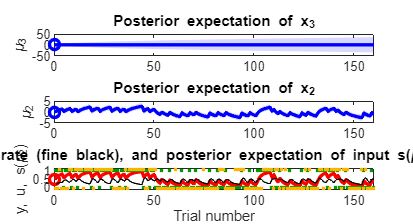

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN 0.0082 2]

 
Parameter estimates for the observation model:
    ze: 1.7124

Model quality:
    LME (more is better): -7

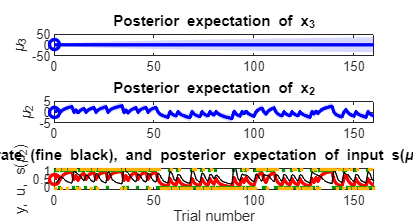

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -0.9771 2]

 
Parameter estimates for the observation model:
    ze: 1.7030

Model quality:
    LME (more is better): -

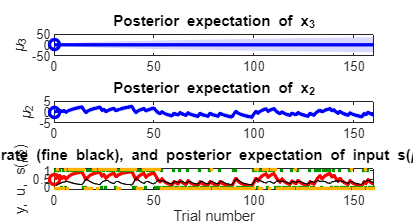

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing

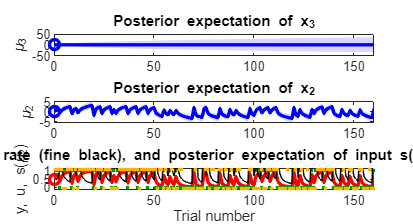

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -0.4094 2]

 
Parameter estimates for the observation model:
    ze: 1.0886

Model quality:
    LME (more is better): -

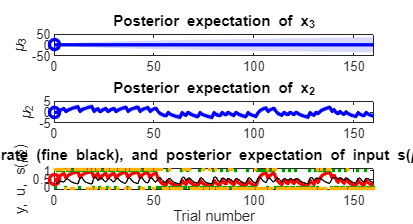

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -3.4813 2]

 
Parameter estimates 

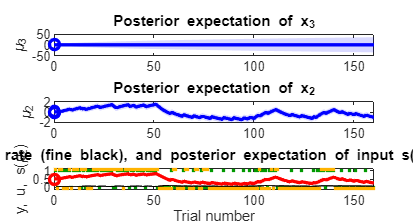

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN 0.1745 2]

 
Parameter estimates for the observation model:
    ze: 0.9827

Model quality:
    LME (more is better): -9

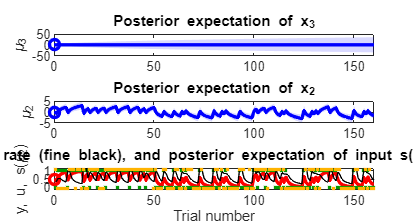

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -0.7879 2]

 
Parameter estimates for the observation model:
    ze: 0.9789

Model quality:
    LME (more is better): -

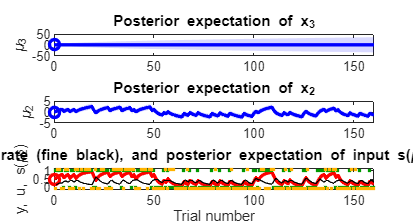

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parame

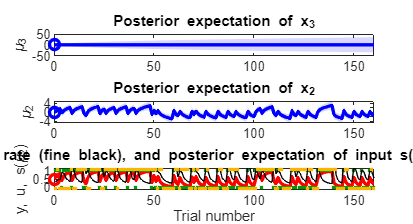

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN 0.0211 2]

 
Parameter estimates for the observation model:
    ze: 1.5153

Model quality:
    LME (more is better): -7

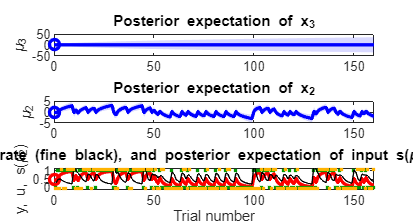

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -1.1220 2]

 
Parameter estimates for the observation model:
    ze: 1.2789

Model quality:
    LME (more is better): -

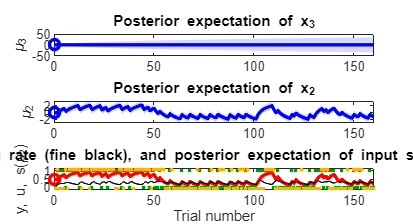

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -1.8207 2]

 
Parameter estimates for the observation model:
    ze: 1.6736

Model quality:
    LME (more is better): -

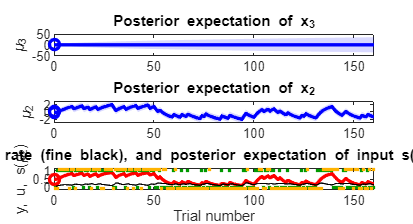

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN 0.4266 2]

 
Parameter estimat

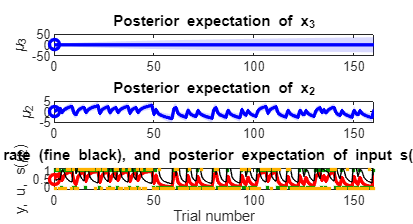

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -0.9507 2]

 
Parameter estimates 

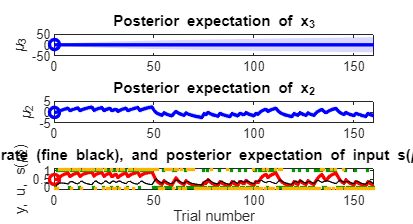

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -1.3605 2]

 
Parameter estimates 

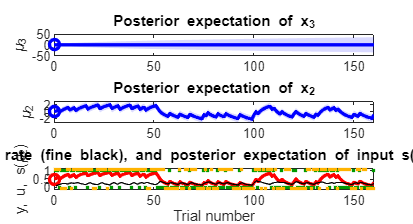

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN 0.2493 2]

 
Parameter estimates f

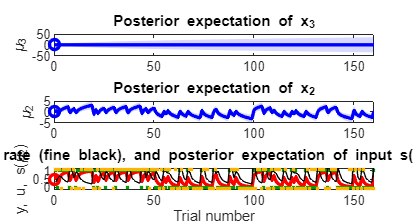

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -0.5099 2]

 
Parameter estimates for the observation model:
    ze: 1.1397

Model quality:
    LME (more is better): -

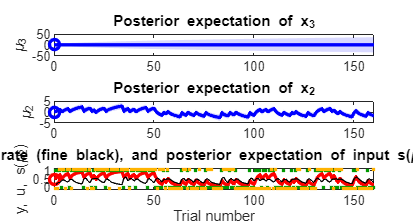

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -0.3403 2]

 
Parameter estimates 

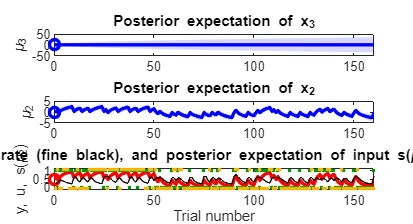

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -0.0106 2]

 
Parameter estimates for the observation model:
    ze: 1.2557

Model quality:
    LME (more is better): -

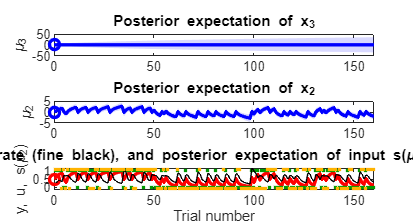

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN 0.5250 2]

 
Parameter estimates for the observation model:
    ze: 0.6763

Model quality:
    LME (more is better): -1

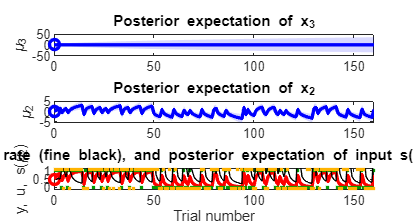

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -0.2651 2]

 
Parameter estimates for the observation model:
    ze: 1.4574

Model quality:
    LME (more is better): -

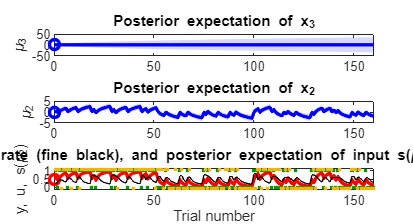

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing

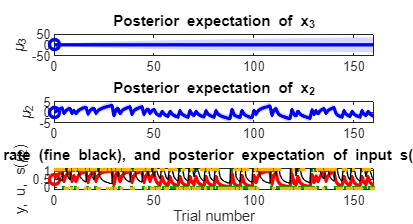

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -0.1233 2]

 
Parameter estimates 

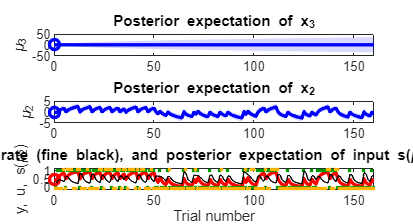

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -1.4388 2]

 
Parameter estimates 

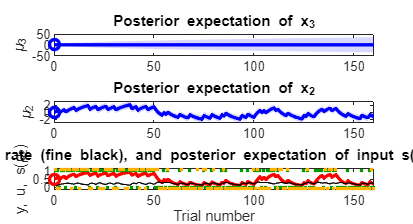

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN 0.3212 2]

 
Parameter estimates f

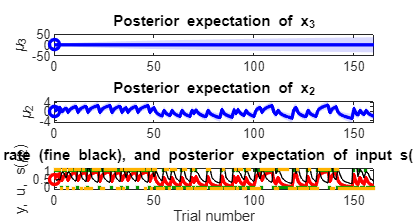

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN 0.7769 2]

Model quality:
    LME 

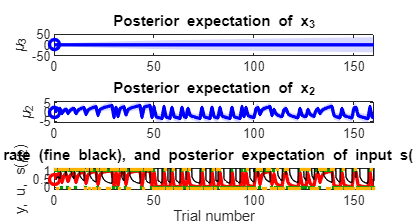

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -0.1340 2]

Model quality:
    LME (more is better): -103.677
    AIC (less is better): 205.7475
    BIC (less is bette

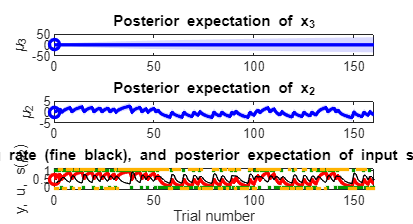

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 

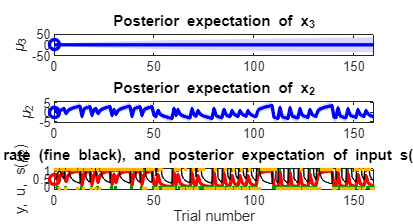

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -2.0337 2]

Model quality:
    LME (more is better): -101.079
    AIC (less is better): 202.1927
    BIC (less is bette

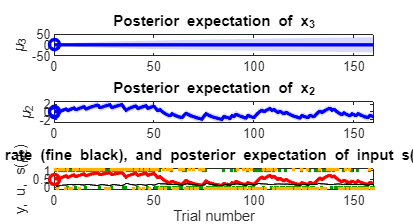

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing

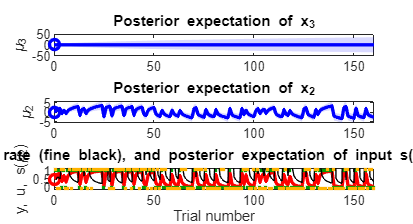

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN 0.3777 2]

Model quality:
    LME 

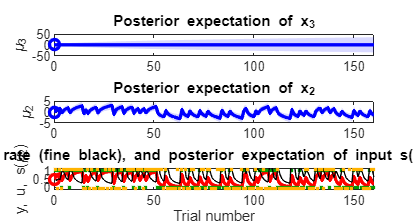

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 

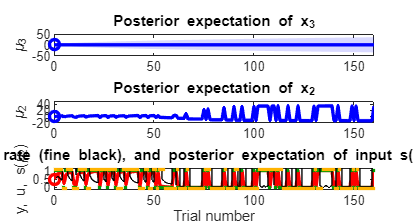

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)

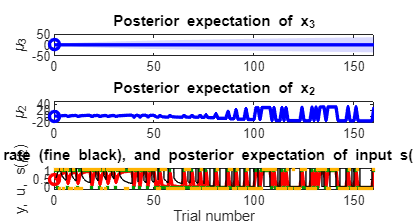

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)

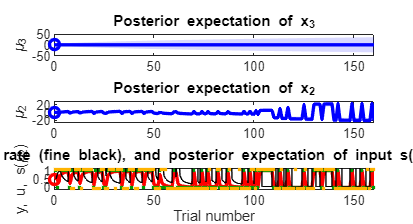

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 

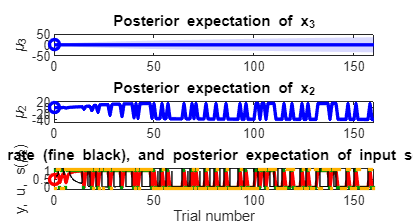

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 

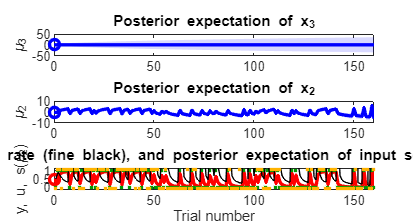

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN 0.7258 2]

Model quality:
    LME (more is better): -88.9021
    AIC (less is better): 167.9129
    BIC (less is better

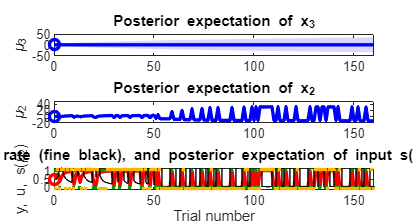

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the l

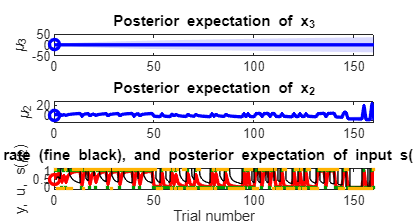

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 

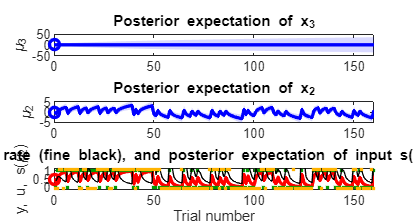

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -0.5985 2]

Model quality:
    LME (more is better): -99.9175
    AIC (less is better): 198.4122
    BIC (less is bette

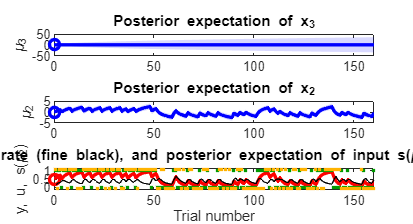

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing

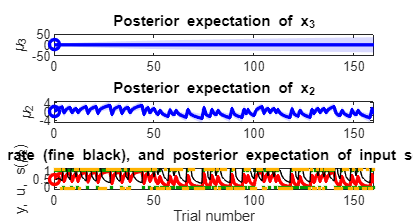

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing

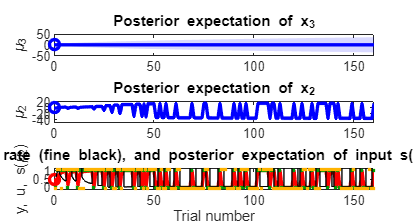

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -0.1320 2]

Model quality:
    LME (more is better): -97.9563
    AIC (less is better): 194.4229
    BIC (less is bette

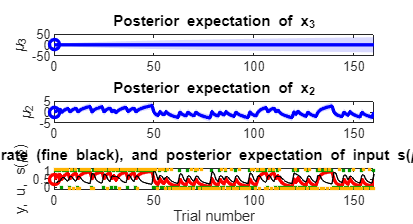

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -1.6740 2]

Model quality:
    LME (more is better): -101.5748
    AIC (less is better): 203.3676
    BIC (less is bett

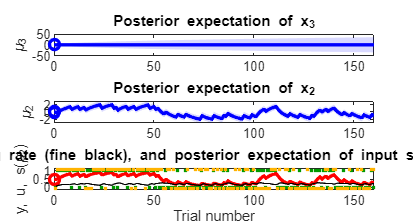

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing

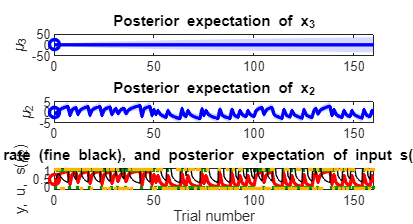

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 

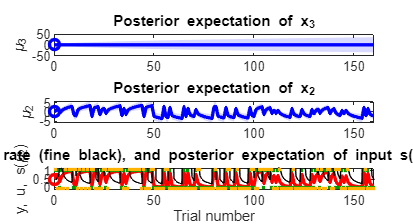

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN 0.1155 2]

Model quality:
    LME (more is better): -93.6622
    AIC (less is better): 184.5016
    BIC (less is better

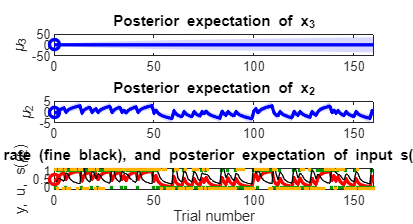

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN 0.0881 2]

Model quality:
    LME (more is better): -97.0919
    AIC (less is better): 191.7161
    BIC (less is better

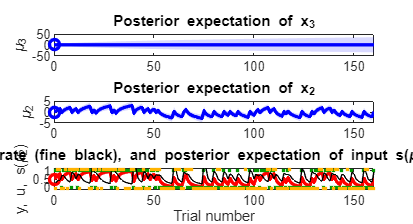

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 

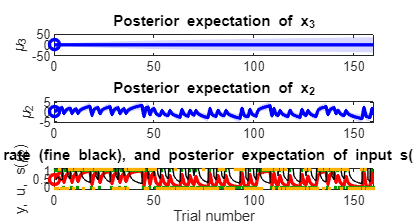

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)

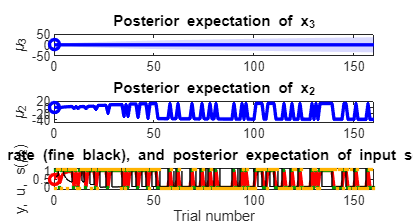

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 

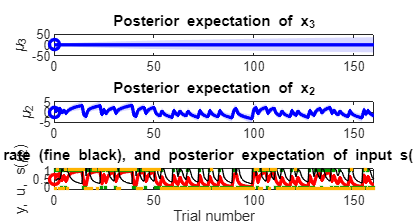

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parame

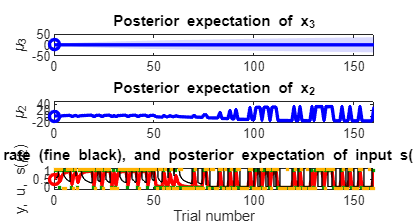

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 

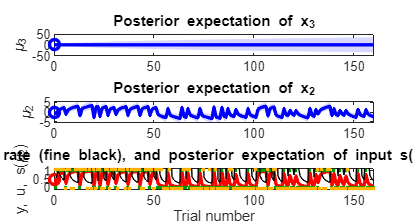

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -0.3844 2]

Model quality:
    LME (more is better): -92.447
    AIC (less is better): 183.0752
    BIC (less is better

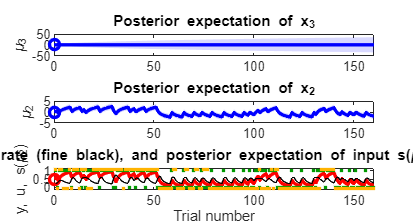

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 

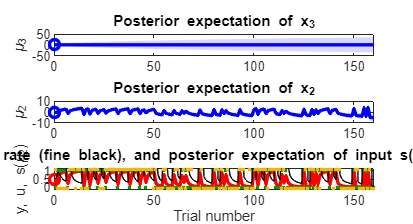

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 

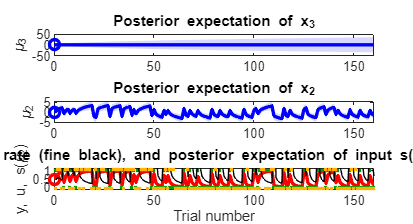

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing

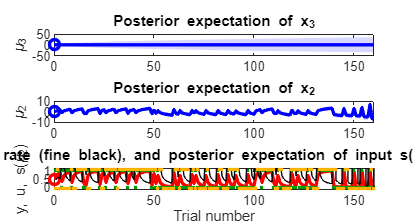

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing

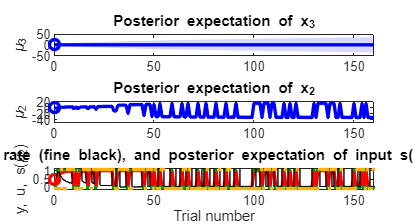

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing

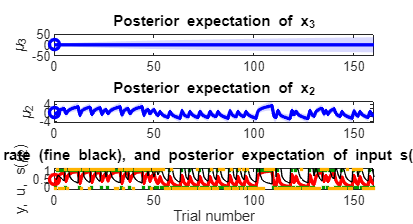

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN 0 2]

Model quality:
    LME (more is better): -91.4799
    AIC (less is better): 182.9111
    BIC (less is better): 18

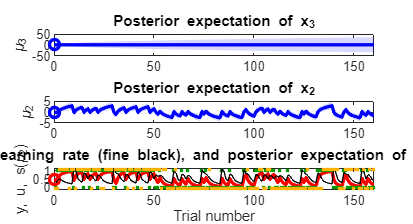

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 

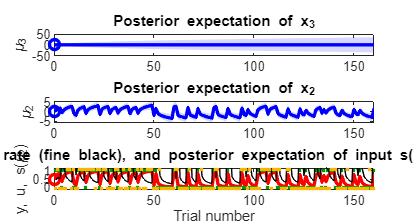

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -0.5989 2]

Model quality:
    LME (more is better): -96.3058
    AIC (less is better): 191.4092
    BIC (less is bette

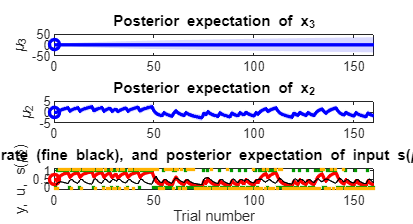

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -0.5007 2]

Model quality:
    LME (more is better): -100.4813
    AIC (less is better): 199.8745
    BIC (less is bett

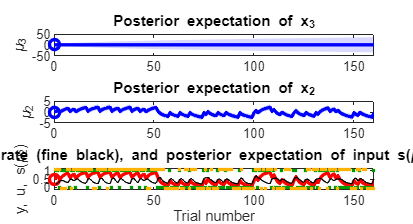

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 

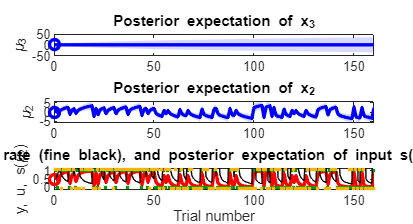

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN 0.2416 2]

Model quality:
    LME (more is better): -96.9777
    AIC (less is better): 190.6088
    BIC (less is better

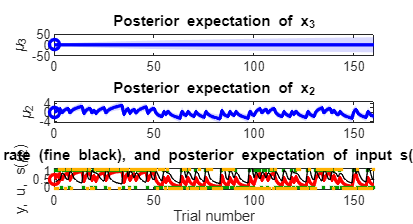

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing

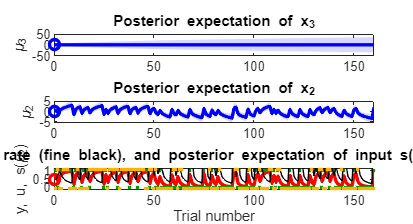

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 

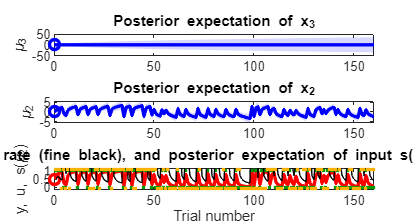

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 

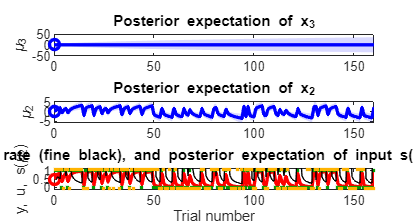

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)

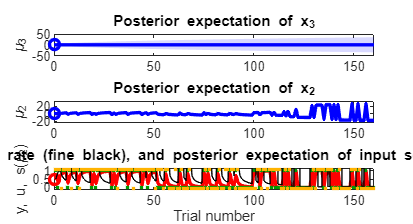

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing

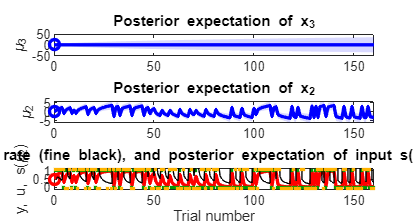

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 

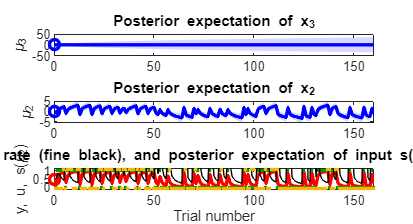

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 0]
      om: [NaN -0.7104 2]

Model quality:
    LME (more is better): -97.8071
    AIC (less is better): 194.4008
    BIC (less is bette

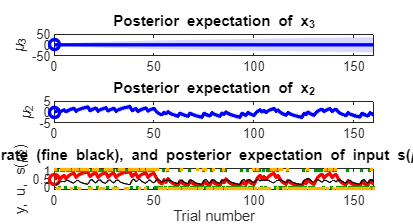

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 
 
Calculating the log-model evidence (LME)...
 
Optimizing...
 

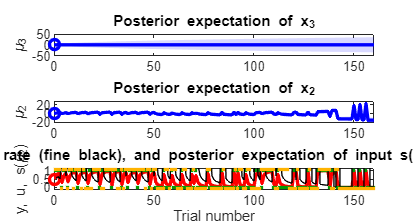

obsNames = {"softmax", "unitsq", "unitsq_mu3"};
obsArgs = {softmax_model_config, unitsq_model_config, unitsq_mu3_config};

for i = 2:numel(obsNames)
    for j = 1:numel(percNames)
        for h = 1:(finaldata1.NewRunIndex(end))
        
        sessiondata = finaldata1(finaldata1.NewRunIndex == h, :);

        if obsNames{i} == "unitsq_mu3" && percNames{j} == "rw"
        continue
        end
        
        fits.(obsNames{i}).(percNames{j})(h) = tapas_fitModel(sessiondata.Choice,...
                                                 sessiondata.Correct_Side,...
                                                 percArgs{j},...
                                                 obsArgs{i},...
                                                 optim_config');
    
        if j == 1
            tapas_rw_binary_plotTraj(fits.(obsNames{i}).(percNames{j})(h));
        elseif j == 5
            tapas_sutton_k1_binary_plotTraj(fits.(obsNames{i}).(percNames{j})(h));
        else
            tapas_ehgf_binary_plotTraj(fits.(obsNames{i}).(percNames{j})(h));
        end
        
        fig = gcf;
        filename = "Fitted_" + percNames{j} + obsNames{i} + ".pdf";
        exportgraphics(fig, filename, 'Append', true);

        lmes.(obsNames{i}).(percNames{j})(h, :) = fits.(obsNames{i}).(percNames{j})(h).optim.LME;
        
        save("fitting_task1.mat", "lmes", "fits")

        end
    end
end

### RW Task 1 Parameter Recovery

rw_task1_param_recov = NaN(size(rw_task1_posterior, 1), 2);

for i = 1:(size(rw_task1_posterior, 1))
    sessiondata = finaldata1(finaldata1.NewRunIndex == i, :);
    
    sim = tapas_simModel(sessiondata.Correct_Side,...
        'tapas_rw_binary',...
        [tapas_logit(0.5, 1), rw_task1_posterior(i, 1)],...
        'tapas_softmax_binary',...
        rw_task1_posterior(i, 2));

    fit = tapas_fitModel(sim.y,...
        sessiondata.Correct_Side,...
        rw_model_config,...
        softmax_model_config,...
        optim_config');

    rw_task1_param_recov(i, 1) = fit.p_prc.al;
    rw_task1_param_recov(i, 2) = fit.p_obs.be;
end

scatter(rw_task1_param_recov(:,1), rw_task1_posterior(:,1))
corrcoef(rw_task1_param_recov(:,1), rw_task1_posterior(:,1))

scatter(rw_task1_param_recov(:,2), rw_task1_posterior(:,2))
corrcoef(rw_task1_param_recov(:,2), rw_task1_posterior(:,2))

save("modelling_task1.mat")

lmes = [lmes.softmax.rw, lmes.softmax.hgf2l, lmes.softmax.hgf3l, lmes.softmax.hgfar1, lmes.softmax.sutton, lmes.unitsq.rw, ...
    lmes.unitsq.hgf2l, lmes.unitsq.hgf3l, lmes.unitsq.hgfar1, lmes.unitsq.sutton, lmes.unitsq_mu3.hgf3l, lmes.unitsq_mu3.hgfar1];
[alpha, exp_r, xp, pxp, bor] = spm_BMS(lmes);

x = ["RW", "2-Level HGF", "3-Level HGF", "Mean-Reverting HGF"];
bar(x, exp_r)
ylabel("p(r|y)")